# Matrices and Vectors

This set of exercises reviews the basics of creating, manipulating and doing arithmetic matrices in MATLAB.  The exercises roughly following the presentation in [Introduction to Applied Linear Algebra – Vectors, Matrices, and Least Squares](https://web.stanford.edu/~boyd/vmls/), Chapter 6.

Each of these exercises is intended to be short.  Most can be solved in 1-2 lines of code.  None of them should take more than 4 lines of code.

## Creating and Indexing Matrices

**Create a matrix **

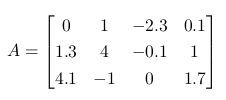

A = [0 1 -2.3 0.2;
    1.3 4 -0.1 1;
    4.1 -1 0 1.7];

Use `size` and `fprintf` functions to print the number of rows and columns in A.  For example

where `m` and `n` are integer values.

s = size(A);
fprintf("A has %d rows and %d columns.\n", s(1), s(2));

A has 3 rows and 4 columns.


**Indexing and slicing**

Use matrix indexing to extract the following from A:

- The element in the 2nd row and 3rd column

- The second row

- The last column

- The submatrix 

A(2,3)

ans = -0.1000

A(2,:)

ans =     1.3000    4.0000   -0.1000    1.0000


A(:,end)

ans =     0.2000
    1.0000
    1.7000


A(2:end, 3:end)

ans =    -0.1000    1.0000
         0    1.7000


**Block matrices**

Create these four matrices

B = [0 2 3];
C = [-1];
D = [2 2 1;
    1 3 5];
E = [4 4]';

Then use those submatrices to concatenate and stack into this new matrix.

Hint: It might be easier to debug to do this one step at a time, incrementally building A from the parts.

A1 = [B; D]

A1 =      0     2     3
     2     2     1
     1     3     5


A2 = [C; E]

A2 =     -1
     4
     4


A = [A1 A2]

A =      0     2     3    -1
     2     2     1     4
     1     3     5     4


**Column representation of a matrix.**

Create threse three 3x1 matrices (vectors) using the commands `zeros`, `ones` and using scalar matrix multiplcation.

         

a0 = zeros(3,1)

a0 =      0
     0
     0


a1 = ones(3,1)

a1 =      1
     1
     1


a2 = 2*ones(3,1)

a2 =      2
     2
     2


a3 = 3*ones(3,1)

a3 =      3
     3
     3


Create a 3x4 matrix from these three columns, where each vector is column.

C = [a0 a1 a2 a3]

C =      0     1     2     3
     0     1     2     3
     0     1     2     3


Create a 4x3 matrix from these three vectors, where each vector is row without transposing the entire matrix C. (Hint: you can transpose each vector.)

R = [a0' ; a1' ; a2' ; a3']

R =      0     0     0
     1     1     1
     2     2     2
     3     3     3


% or
R = C'

R =      0     0     0
     1     1     1
     2     2     2
     3     3     3


Diagonal matrices

Use the `diag` function to create this matrix.

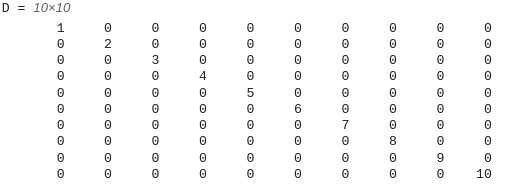

D = diag(1:10)

D =      1     0     0     0     0     0     0     0     0     0
     0     2     0     0     0     0     0     0     0     0
     0     0     3     0     0     0     0     0     0     0
     0     0     0     4     0     0     0     0     0     0
     0     0     0     0     5     0     0     0     0     0
     0     0     0     0     0     6     0     0     0     0
     0     0     0     0     0     0     7     0     0     0
     0     0     0     0     0     0     0     8     0     0
     0     0     0     0     0     0     0     0     9     0
     0     0     0     0     0     0     0     0     0    10


**Transpose of block matrix, matrix equivalence and **`all`

Create two matrices 2x2 matrices

A = reshape(1:4,[2,2])

A =      1     3
     2     4


B = reshape(11:14, [2, 2])

B =     11    13
    12    14


Show that $\left[A \, \, B\right]^T = \left[ \matrix{A^T \cr B^T}\right] $.   To show that two matrices, M and N,  are equivalent use `all( M == N, "all")``.`

[A B]'

ans =      1     2
     3     4
    11    12
    13    14


[A' ; B']

ans =      1     2
     3     4
    11    12
    13    14


all([A B]' == [A' ; B'], 'all')

ans = logical
   1


**Transponse of sum**

Use the same A and B matrices to show that


$$(A+B)^T = A^T + B^T$$


all(A' + B' == (A + B)', "all")

ans = logical
   1


**Scalar-matrix multiplication**

Create a 3x2 matrix of uniformly distributed random integers using the `randi` function. (You choose the `imax` parameter.)

A = randi(10, 3,2)

A =      2     4
     9     6
     7     5


Show that $( \beta + \gamma) A = \beta A+ \gamma A$

where $\beta
$ and $\gamma$ are integer (numeric doubles with integer values) scalars of your choosing. 

beta = 3;
gamma = 4;
all( (beta+gamma)*A == (beta*A + gamma*A) , "all")

ans = logical
   1


Does te same equivalence hold if A is a uniformaly distributed decimal number from `rand` function? What about if the scalars are non-integers?

**Matrix-vector multiplication**

Create a matrix and a vector to show that this simple example is true

A = [0 2 -1; -2 1 1]

A =      0     2    -1
    -2     1     1


b = [2 1 -1]'

b =      2
     1
    -1


A*b

ans =      3
    -4


Given the five element vector   $a = \left\{ \matrix{1 \cr 2 \cr 3 \cr 4 \cr 5} \right\}$.

Choose the vector $b$ so that the the inner product $c = a^T b$ is the mean of $a$.  ($c$ is a scalar and should be 3.)

a = [1:5]'

a =      1
     2
     3
     4
     5


b = ones(length(a), 1)/length(a)

b =     0.2000
    0.2000
    0.2000
    0.2000
    0.2000


c = a' * b

c = 3